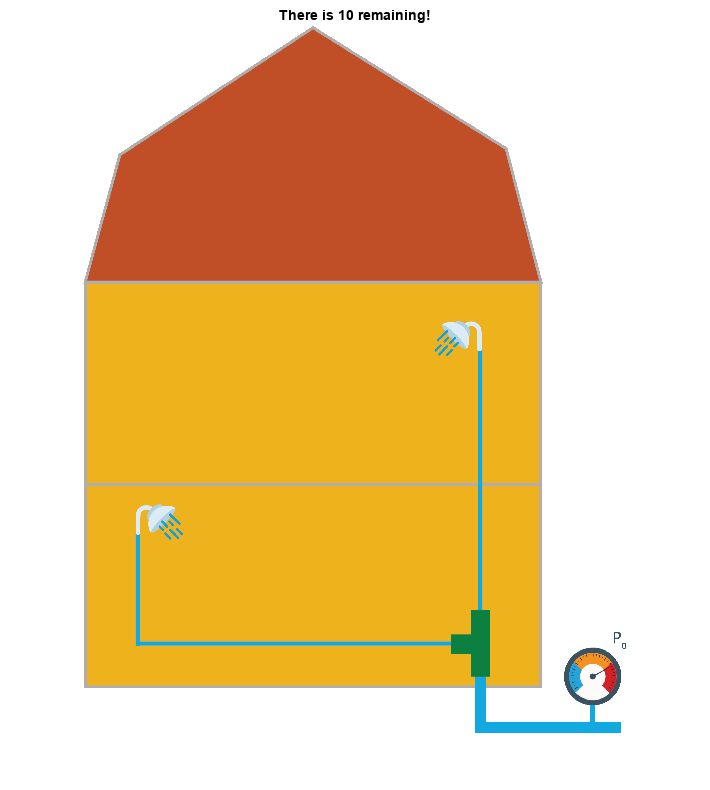

clear
load ROI2.mat
[I,~,A] = imread(gTruth.DataSource.Source{1}); 
data = boxLabelDatastore(gTruth.LabelData);
box = data.LabelData{1,1};
label = data.LabelData{1,2};
found = zeros(size(box,1),1);
tobefound = size(found, 1);
img = imshow(I);
while ~all(found)
    title("There is "+num2str(tobefound-sum(found))+" remaining!")
    [xi,yi] = ginput(1); 
    idx = box(:,1) <= xi & xi <= box(:,1)+box(:,3) ...
        & box(:,2) <= yi & yi <= box(:,2)+box(:,4);
    idx = find(idx);
    found(idx) = 1;
    if ~isempty(idx)
        img.CData = insertObjectAnnotation(img.CData,"rectangle",box(idx,:),label(idx),FontSize=32);
    else
    end
end
title("You found all the head losses!")

close all